This script finds a conservative torque range for the Otbot by taking into account the torque-velocity curve of its motors, and assuming ellipsoidal bounds for the platform twist $\mathbf{\dot{p}}$. The user has to specify some geometric and motor parameters in Sections 2 and 6 below.

## 1 - Initializations

% Clear all variables, close all figures, and clear the command window
clearvars 
close all
clc

% Load forward kinematic Jacobian M_FIK
load('forward_inverse_jacobians.mat')

% Symbolic variables used below
syms l_1 l_2 r 
syms v_m omega_m

% Font size used in plot legends
legendfontsize = 15;

## 2 - Dimensions and maximum speeds allowed

l1_value = 0.25;   % Value of the pivot offset [m]
l2_value = 0.2;    % Value of the semiaxis length [m]
r_value = 0.1;     % Value of the wheel radius [m]
vm_value = 2;      % Value of the maximum speed of the pivot point [m/s]
om_value = 2;      % Value of the maximum angular velocity alpha_dot of the platform [m/s]

## 3 - Define ellipsoid of platform velocities

Let $v_m$ and $\omega_m$ denote respectively the maximum velocity allowed for the pivot point velocity and the platform angular velocity $\dot{\alpha}$ respectively. Then, the ellipsoid of platform velocities has the form $\mathbf{\dot{p}}^T \cdot \mathbf{S} \cdot \mathbf{\dot{p}} \leq 1$ where $\mathbf{S}$ defines an axis-aligned ellipsoid centred at the origin of the $\mathbf{\dot{p}}$ space, with semiaxes lengths $v_m$, $v_m$, and $\omega_m$ along the $x$, $y$, and $z$ axes respectively. In limiting $\mathbf{\dot{p}}$ in this way, we are assuming that (1) the maximum value of $\dot{\alpha}$ occurs when the pivot point is stopped, and that (2) the value of $\dot{\alpha}$ approaches zero when the pivot point approaches its maximum linear velocity.

% Symbolic matrix defining the ellipsoid of platform velocities
Ss = [1/v_m^2 0 0; 0 1/v_m^2 0; 0 0 1/omega_m^2]

$$Ss = \left[\begin{array}{ccc} \frac{1}{{v_{m}}^{2}} & 0 & 0\\ 0 & \frac{1}{{v_{m}}^{2}} & 0\\ 0 & 0 & \frac{1}{{\omega_{m}}^{2}} \end{array}\right]$$


% Evaluate Ss for the values of the Otbot parameters
Sr = double(subs(Ss,[v_m,omega_m],[vm_value,om_value]))

Sr =     0.2500         0         0
         0    0.2500         0
         0         0    0.2500


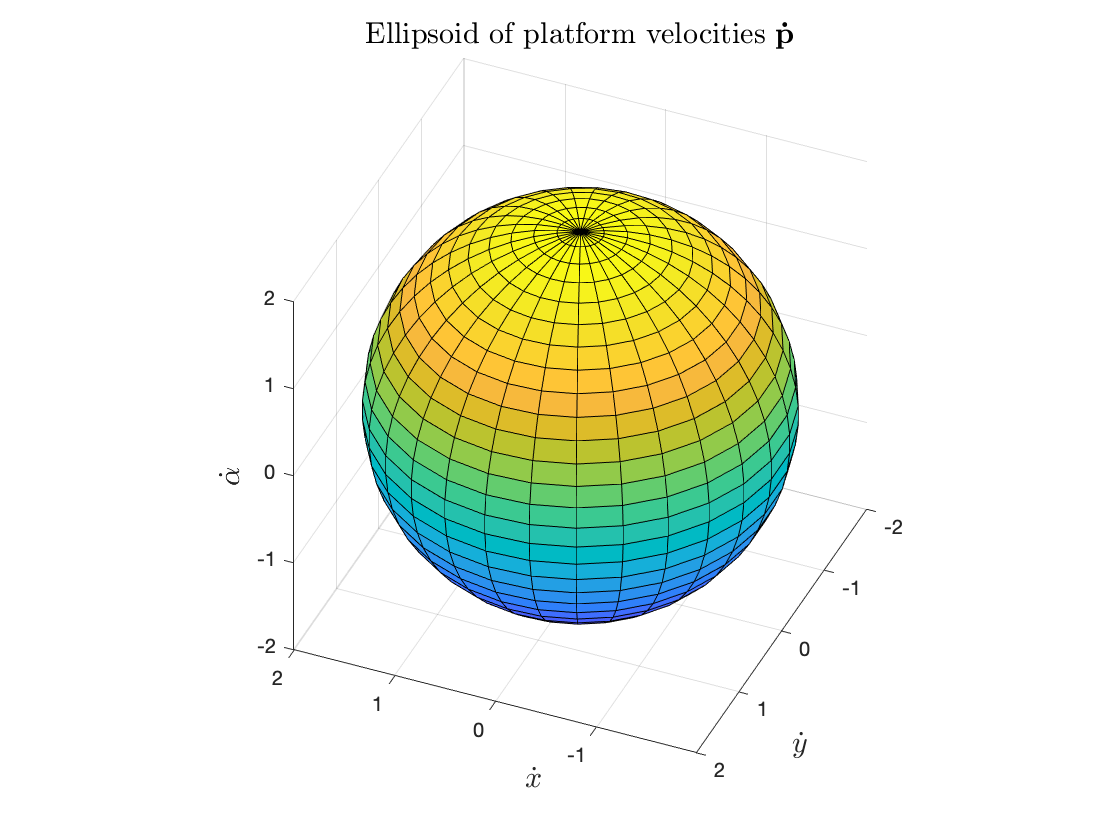


% Draw ellipsoid
Draw_Ellipsoid(Sr);
title('Ellipsoid of platform velocities $\mathbf{\dot{p}}$','Interpreter','latex','FontSize',legendfontsize)
xlabel('$\dot{x}$','Interpreter','latex','FontSize',legendfontsize)
ylabel('$\dot{y}$','Interpreter','latex','FontSize',legendfontsize)
zlabel('$\dot{\alpha}$','Interpreter','latex','FontSize',legendfontsize)
view([1,1,1])

## 4 - Obtain corresponding ellipsoid of actuator velocities

% Symbolic matrix defining the ellipsoid of wheel velocities
Qs = simplify(MFIK_of_q.' * Ss * MFIK_of_q)

$$Qs = \left[\begin{array}{ccc} \frac{r^{2}\,\left({l_{1}}^{2}\,{\omega_{m}}^{2}+{l_{2}}^{2}\,{\omega_{m}}^{2}+{v_{m}}^{2}\right)}{4\,{l_{2}}^{2}\,{\omega_{m}}^{2}\,{v_{m}}^{2}} & -\frac{r^{2}\,\left({l_{1}}^{2}\,{\omega_{m}}^{2}-{l_{2}}^{2}\,{\omega_{m}}^{2}+{v_{m}}^{2}\right)}{4\,{l_{2}}^{2}\,{\omega_{m}}^{2}\,{v_{m}}^{2}} & \frac{r}{2\,l_{2}\,{\omega_{m}}^{2}}\\ -\frac{r^{2}\,\left({l_{1}}^{2}\,{\omega_{m}}^{2}-{l_{2}}^{2}\,{\omega_{m}}^{2}+{v_{m}}^{2}\right)}{4\,{l_{2}}^{2}\,{\omega_{m}}^{2}\,{v_{m}}^{2}} & \frac{r^{2}\,\left({l_{1}}^{2}\,{\omega_{m}}^{2}+{l_{2}}^{2}\,{\omega_{m}}^{2}+{v_{m}}^{2}\right)}{4\,{l_{2}}^{2}\,{\omega_{m}}^{2}\,{v_{m}}^{2}} & -\frac{r}{2\,l_{2}\,{\omega_{m}}^{2}}\\ \frac{r}{2\,l_{2}\,{\omega_{m}}^{2}} & -\frac{r}{2\,l_{2}\,{\omega_{m}}^{2}} & \frac{1}{{\omega_{m}}^{2}} \end{array}\right]$$


% Evaluate Q for the values of the Otbot 1 parameters
Qr = double(subs(Qs,[l_1,l_2,r,v_m,omega_m],[l1_value,l2_value,r_value,vm_value,om_value]))

Qr =     0.0172   -0.0160    0.0625
   -0.0160    0.0172   -0.0625
    0.0625   -0.0625    0.2500


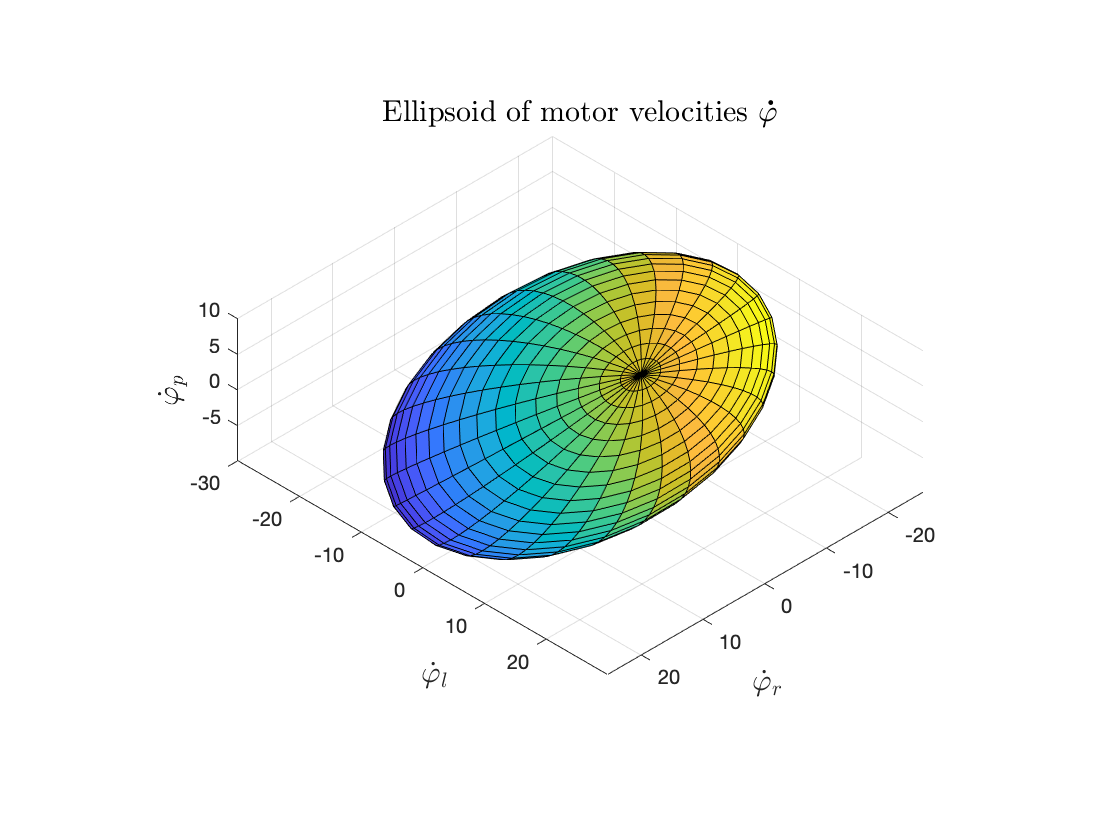


% Draw ellipsoid in 3D view
Draw_Ellipsoid(Qr);
title('Ellipsoid of motor velocities $\mathbf{\dot{\varphi}}$','Interpreter','latex','FontSize',legendfontsize)
xlabel('$\dot{\varphi}_r$','Interpreter','latex','FontSize',legendfontsize)
ylabel('$\dot{\varphi}_l$','Interpreter','latex','FontSize',legendfontsize)
zlabel('$\dot{\varphi}_p$','Interpreter','latex','FontSize',legendfontsize)
view([1,1,1])

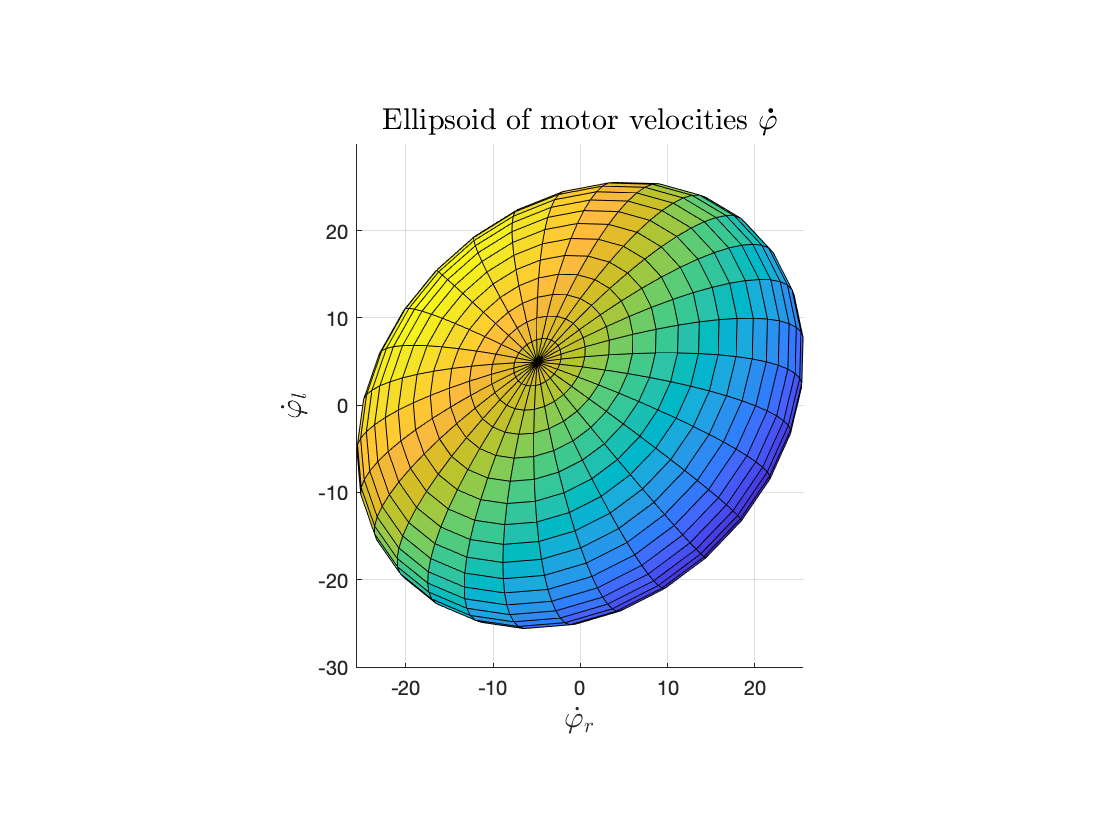


% Project ellipsoid onto the (x,y) plane
Draw_Ellipsoid(Qr);
title('Ellipsoid of motor velocities $\mathbf{\dot{\varphi}}$','Interpreter','latex','FontSize',legendfontsize)
xlabel('$\dot{\varphi}_r$','Interpreter','latex','FontSize',legendfontsize)
ylabel('$\dot{\varphi}_l$','Interpreter','latex','FontSize',legendfontsize)
zlabel('$\dot{\varphi}_p$','Interpreter','latex','FontSize',legendfontsize)
view([0,0,1])

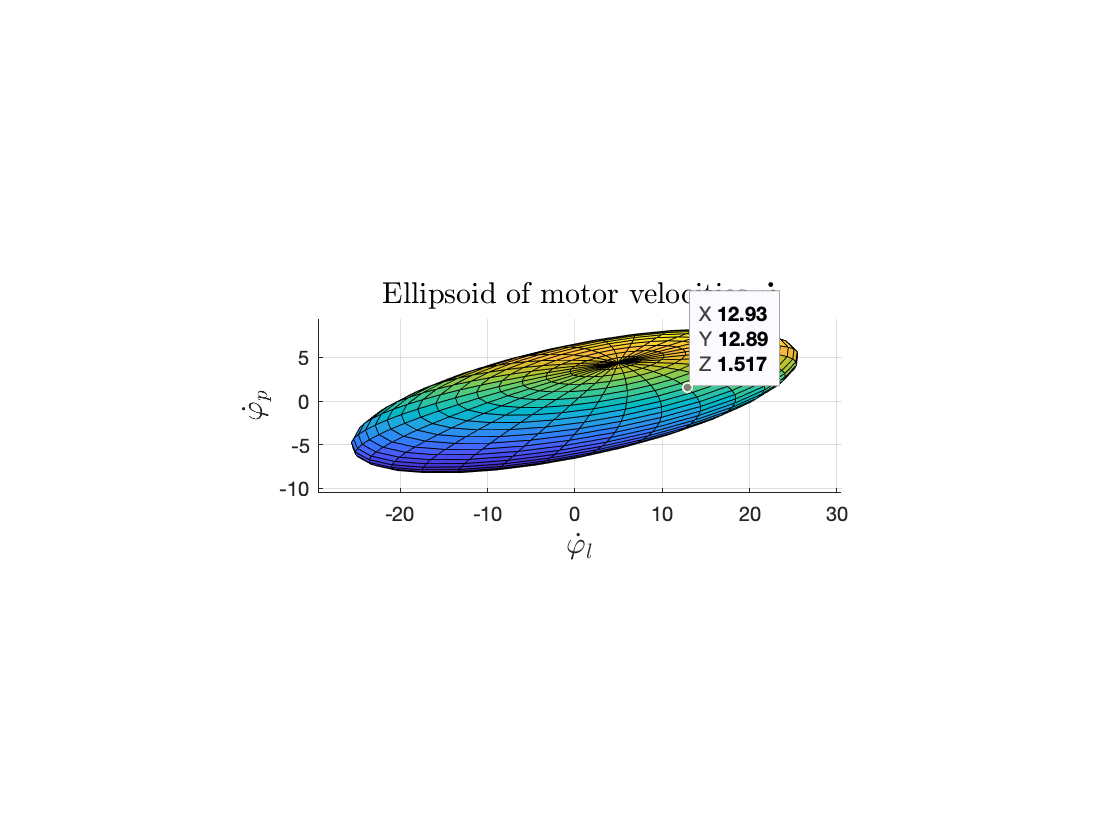


% Project ellipsoid onto the (y,z) plane
Draw_Ellipsoid(Qr);
title('Ellipsoid of motor velocities $\mathbf{\dot{\varphi}}$','Interpreter','latex','FontSize',legendfontsize)
xlabel('$\dot{\varphi}_r$','Interpreter','latex','FontSize',legendfontsize)
ylabel('$\dot{\varphi}_l$','Interpreter','latex','FontSize',legendfontsize)
zlabel('$\dot{\varphi}_p$','Interpreter','latex','FontSize',legendfontsize)
view([1,0,0])

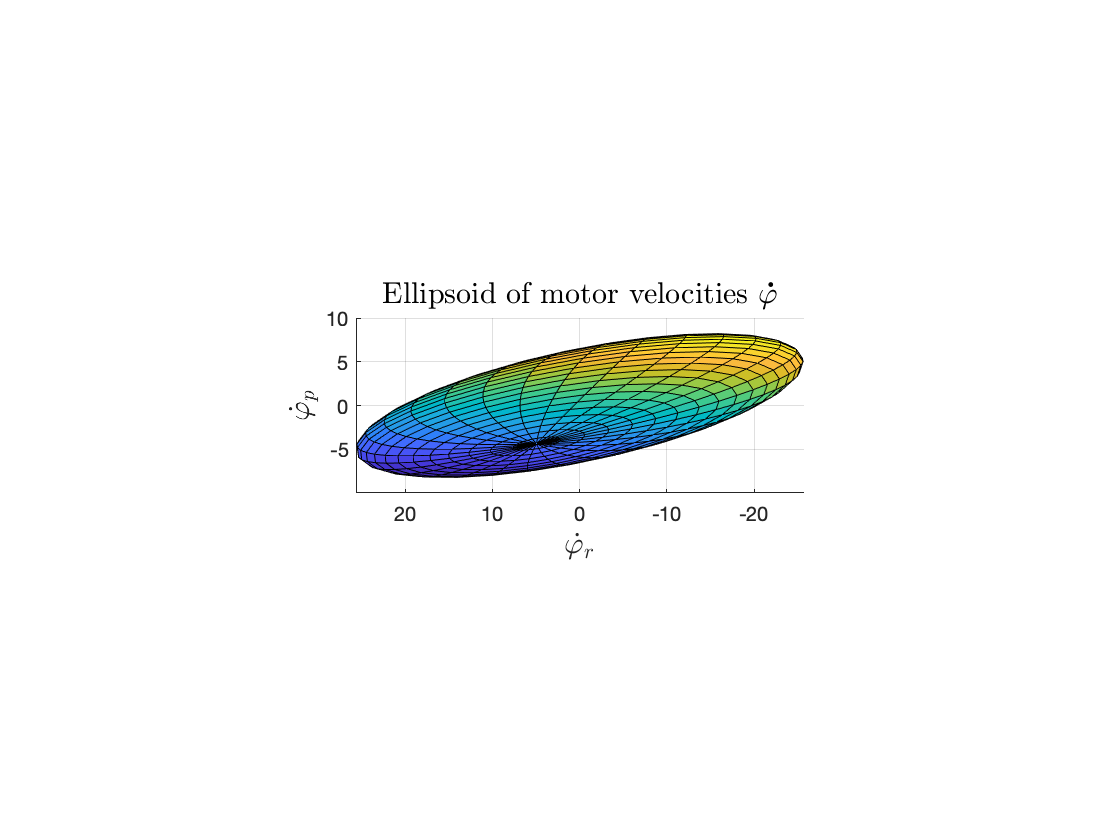


% Project ellipsoid onto the (x,z) plane
Draw_Ellipsoid(Qr);
title('Ellipsoid of motor velocities $\mathbf{\dot{\varphi}}$','Interpreter','latex','FontSize',legendfontsize)
xlabel('$\dot{\varphi}_r$','Interpreter','latex','FontSize',legendfontsize)
ylabel('$\dot{\varphi}_l$','Interpreter','latex','FontSize',legendfontsize)
zlabel('$\dot{\varphi}_p$','Interpreter','latex','FontSize',legendfontsize)
view([0,1,0])

## 5 - Find maximum and minimum values of the ellipsoid along each dimension

syms x y z

% Equation of the motor velocity ellipsoid
v = [x;y;z];
ellipsoid_eqn = v.' * Qr * v == 1;

% Gradient of the LHS (gives vector orthogonal to ellipsoid)
grad = 2 * v.' * Qr;

% Max values of ellipsoid along x dimension
eqns = [ellipsoid_eqn, grad(2)==0, grad(3)==0];
Sols = solve(eqns,[x y z]);
max_phidot_r = abs(double(Sols.x(1)))

max_phidot_r = 25.6125


% Max values of ellipsoid along y dimension
eqns = [ellipsoid_eqn, grad(1)==0, grad(3)==0];
Sols = solve(eqns,[x y z]);
max_phidot_l = abs(double(Sols.y(1)))

max_phidot_l = 25.6125


% Max values of ellipsoid along z dimension
eqns = [ellipsoid_eqn, grad(1)==0, grad(2)==0];
Sols = solve(eqns,[x y z]);
max_phidot_p = abs(double(Sols.z(1)))

max_phidot_p = 8.2462

## 6 - Motor and gear parameters assumed

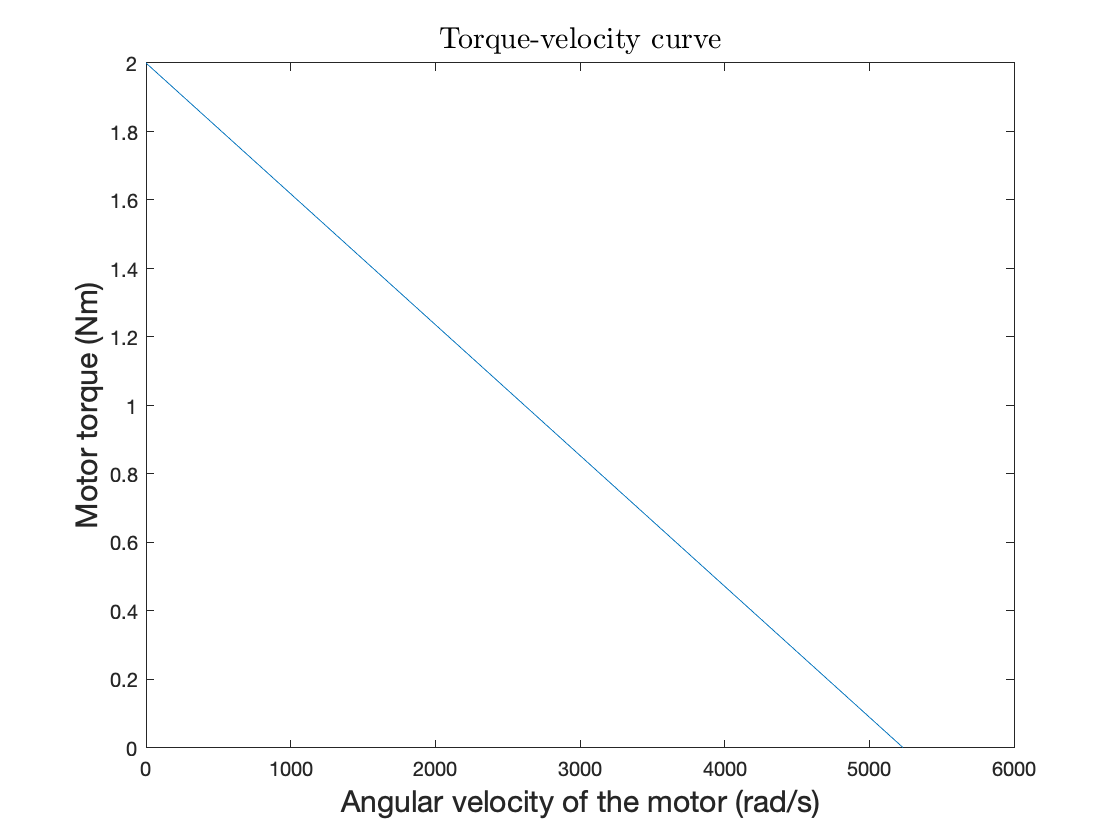


N_wheel = 50;               % Wheel gear reduction factor
N_pivot = 150;              % Pivot gear reduction factor
stall_torque = 2;           % Stall torque of the motor [Nm]
no_load_speed_rpm = 50000;  % Max speed, assuming zero motor torque [rpm]
peak_torque = 7.20;         % Maximum allowed torque for short periods of time [Nm]
                            % ... at the cost of heating the motor

% Max. speed in rad/s
no_load_speed = no_load_speed_rpm * (2*pi/60);

% Slope of the torque-velocity curve of the motors
slope = - stall_torque / no_load_speed;

% Plot torque-velocity curve of the motor
xs = linspace(0,no_load_speed, 2);
ys = stall_torque + slope * xs;
plot(xs,ys)
title('Torque-velocity curve','Interpreter','latex','FontSize',legendfontsize)
xlabel('Angular velocity of the motor (rad/s)','FontSize',legendfontsize)
ylabel('Motor torque (Nm)','FontSize',legendfontsize)

## 7 - Find conservative torque range

% Maximum speed of the wheel motors
max_speed_wheel_motor = N_wheel * max_phidot_r

max_speed_wheel_motor = 1.2806e+03


% Maximum speed of the pivot motors
max_speed_pivot_motor = N_pivot * max_phidot_p

max_speed_pivot_motor = 1.2369e+03


% Maximum torque allowed when the wheels turn at max speed
max_motor_torque_wheels = stall_torque + slope * max_speed_wheel_motor

max_motor_torque_wheels = 1.5108

max_actuator_torque_wheels = max_motor_torque_wheels * N_wheel

max_actuator_torque_wheels = 75.5419


% Maximum torque allowed when the pivot turns at max speed
max_motor_torque_pivot = stall_torque + slope * max_speed_pivot_motor

max_motor_torque_pivot = 1.5275

max_actuator_torque_pivot = max_motor_torque_pivot * N_pivot

max_actuator_torque_pivot = 229.1290


% Conclusion
fprintf(' \n\n\n');

fprintf('Conclusion: \n');

Conclusion: 


fprintf('\t* Maximum actuation torque at a wheel = %.3f Nm\n', max_actuator_torque_wheels);

	* Maximum actuation torque at a wheel = 75.542 Nm


fprintf('\t* Maximum actuation torque at the pivot = %.3f Nm\n', max_actuator_torque_pivot);

	* Maximum actuation torque at the pivot = 229.129 Nm


## Appendix - Function Draw_Ellipsoid

function Draw_Ellipsoid(Q)
% Function adapted from https://bit.ly/3ssTUL2
% Draws the origin-centered ellipsoid 
%    x' * Q * x = 1
% so Q must be a positive-definite symmetric matrix

M = [Q(1,1) Q(1,2) Q(1,3) 0;
     Q(2,1) Q(2,2) Q(2,3) 0;
     Q(3,1) Q(3,2) Q(3,3) 0;
     0      0      0      1];

S = M^0.5;

n = 30;

[th, ph] = meshgrid(linspace(0, 2*pi, n), linspace(0, pi, n));

spherepoints = zeros(4, n, n);
spherepoints(1, :,:) = cos(th) .* sin(ph);
spherepoints(2, :,:) = sin(th) .* sin(ph);
spherepoints(3, :,:) = cos(ph);
spherepoints(4, :, :) = 1;

sp = reshape(spherepoints, 4, []); 

epoints = S \ sp;
epoints = reshape(epoints, 4, n, n);

surf(squeeze(epoints(1, :,:)),...
    squeeze(epoints(2,:,:)),...
    squeeze(epoints(3,:,:)));

set(gca, 'DataAspectRatio', [1,1,1]);

axis vis3d

figure(gcf);

end